% Hough transform
RGB = imread("images\meta\0.png");
I  = im2gray(RGB);

% Extract edges.
BW = edge(I,'canny');

% Calculate Hough transform.
[H,T,R] = hough(BW,'RhoResolution',0.5,'Theta',-90:0.5:89);
H

H =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

T

T =   -90.0000  -89.5000  -89.0000  -88.5000  -88.0000  -87.5000  -87.0000  -86.5000  -86.0000  -85.5000  -85.0000  -84.5000  -84.0000  -83.5000  -83.0000  -82.5000  -82.0000  -81.5000  -81.0000  -80.5000  -80.0000  -79.5000  -79.0000  -78.5000  -78.0000  -77.5000  -77.0000  -76.5000  -76.0000  -75.5000  -75.0000  -74.5000  -74.0000  -73.5000  -73.0000  -72.5000  -72.0000  -71.5000  -71.0000  -70.5000  -70.0000  -69.5000  -69.0000  -68.5000  -68.0000  -67.5000  -67.0000  -66.5000  -66.0000  -65.5000


R

R =  -140.5000 -140.0000 -139.5000 -139.0000 -138.5000 -138.0000 -137.5000 -137.0000 -136.5000 -136.0000 -135.5000 -135.0000 -134.5000 -134.0000 -133.5000 -133.0000 -132.5000 -132.0000 -131.5000 -131.0000 -130.5000 -130.0000 -129.5000 -129.0000 -128.5000 -128.0000 -127.5000 -127.0000 -126.5000 -126.0000 -125.5000 -125.0000 -124.5000 -124.0000 -123.5000 -123.0000 -122.5000 -122.0000 -121.5000 -121.0000 -120.5000 -120.0000 -119.5000 -119.0000 -118.5000 -118.0000 -117.5000 -117.0000 -116.5000 -116.0000


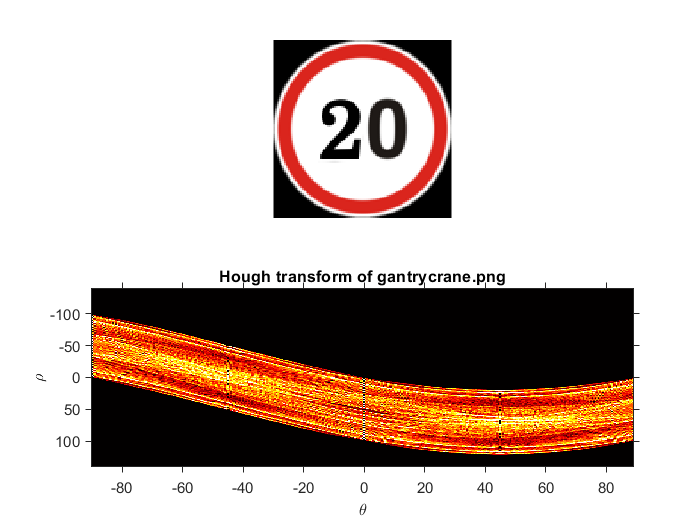


% Display the original image and the Hough matrix.
subplot(2,1,1);
imshow(RGB);

subplot(2,1,2);
imshow(imadjust(rescale(H)),'XData',T,'YData',R,...
      'InitialMagnification','fit');

xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
colormap(gca,hot);